clear all; close all; clc;

Re = 6378;
hp = 622;
ha = 35786;

rp = Re + hp;
ra = Re + ha;


## Problem 1

a = 0.5*(rp + ra);
e = (ra - rp) / (ra + rp);
b = a*sqrt(1 - e^2);
fprintf("Semi minor axis %f [km] \n", b);

Semi minor axis 17179.871944 [km] 


## Problem 2

% Ellipse w.r.t the origin
ellipse_o = @(theta) [a*cos(theta); b*sin(theta)]; 
d1 = norm(ellipse_o(0.9) + [a*e; 0]);
fprintf("Distance from Earth with theta=2.1 is %f [km]\n",d1)

Distance from Earth with theta=2.1 is 35511.146462 [km]


## Problem 3

ge = 9.81e-3;
mu_e = ge*Re^2;
vis_viva = @(r) sqrt(mu_e * (2/r - 1/a));
r3 = norm(ellipse_o(2.4) + [a*e; 0]);
v3 = vis_viva(r3);
fprintf("The velocity is %f [km/s]\n",v3);

The velocity is 7.243484 [km/s]


## Problem 4

% Radius of curvature
RoC = @(theta) (a^2*sin(theta)^2 + b^2*cos(theta)^2)^1.5 / a / b;
rho4 = RoC(1.0);
fprintf("The radius of curvature is %f [km]\n",rho4)

The radius of curvature is 27596.158115 [km]


## Problem 5

the = 0.6

the = 0.6000


en = @(x,y) [2*b^2*x; 2*a^2*y] / norm([2*b^2*x; 2*a^2*y]);
et = @(x,y) [-2*a^2*y; 2*b^2*x] / norm([2*b^2*x; 2*a^2*y]);
r = @(p) [-a*e-a*cos(p); -b*sin(p)];
rhat = @(p) r(p) / norm(r(p));
as = @(p) (mu_e / norm(r(p))^2 * 1000);
as_vec = @(p) (mu_e / norm(r(p))^2 * 1000) * rhat(p);

at = @(p,x,y) dot(as_vec(p),et(x,y));
an = @(p,x,y) dot(as_vec(p),en(x,y));

AT = at(the,a*cos(the),b*sin(the))

AT = 0.1306

AN = an(the,a*cos(the),b*sin(the))

AN = -0.2261

## Problem 6

the = 2.4

the = 2.4000


en = @(x,y) [2*b^2*x; 2*a^2*y] / norm([2*b^2*x; 2*a^2*y]);
et = @(x,y) [-2*a^2*y; 2*b^2*x] / norm([2*b^2*x; 2*a^2*y]);
r = @(p) [-a*e-a*cos(p); -b*sin(p)];
rhat = @(p) r(p) / norm(r(p));
as = @(p) (mu_e / norm(r(p))^2 * 1000);
as_vec = @(p) (mu_e / norm(r(p))^2 * 1000) * rhat(p);

at = @(p,x,y) dot(as_vec(p),et(x,y));
an = @(p,x,y) dot(as_vec(p),en(x,y));

AT = at(the,a*cos(the),b*sin(the))

AT = 1.6814

AN = an(the,a*cos(the),b*sin(the))

AN = -2.4323

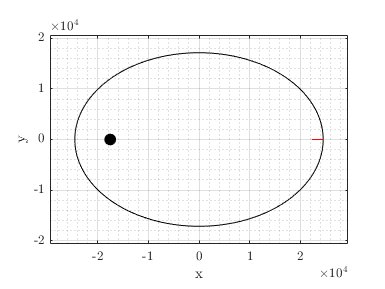

fig = figure(1);
ang = linspace(0,2*pi,1000);
x = a*cos(ang); y = b*sin(ang);
[A_t,A_n,A_s] = accels(ang(1),mu_e,a,b,e); 
A_t = A_t*10000; A_n = A_n*10000; A_s = A_s*10000;
plot(x,y,'-k');
hold on;
plot(-a*e,0,'.k','MarkerSize',30)
hh1(1) = line([x(1), x(1)+A_t(1)], [y(1), y(1)+A_t(2)], 'Color', 'g');
hh1(2) = line([x(1), x(1)+A_n(1)], [y(1), y(1)+A_n(2)], 'Color', 'b');
hh1(3) = line([x(1), x(1)+A_s(1)], [y(1), y(1)+A_s(2)], 'Color', 'r');
xlabel('x'); ylabel('y');
axis equal; grid on; grid minor; box on;
axis([-1.2*a 1.2*a -1.2*b 1.2*b]);

tic;     % start timing
for id = 1:length(ang)
   [A_t,A_n,A_s] = accels(ang(id),mu_e,a,b,e); 
   A_t = A_t*10000; A_n = A_n*10000; A_s = A_s*10000;
   % Update XData and YData
   set(hh1(1),'XData',[x(id),x(id)+A_t(1)],'YData',[y(id),y(id)+A_t(2)]);
   set(hh1(2),'XData',[x(id),x(id)+A_n(1)],'YData',[y(id),y(id)+A_n(2)]);
   set(hh1(3),'XData',[x(id),x(id)+A_s(1)],'YData',[y(id),y(id)+A_s(2)]);

   drawnow;
end

fprintf('Animation (Smart update): %0.2f sec\n', toc);

Animation (Smart update): 32.29 sec


function [AT,AN,AS] = accels(the,mu_e,a,b,e)
    en = @(x,y) [2*b^2*x; 2*a^2*y] / norm([2*b^2*x; 2*a^2*y]);
    et = @(x,y) [-2*a^2*y; 2*b^2*x] / norm([2*b^2*x; 2*a^2*y]);
    r = @(p) [-a*e-a*cos(p); -b*sin(p)];
    rhat = @(p) r(p) / norm(r(p));
    as_vec = @(p) (mu_e / norm(r(p))^2) * 1000 * rhat(p);
    
    at = @(p,x,y) dot(as_vec(p),et(x,y)) * et(x,y);
    an = @(p,x,y) dot(as_vec(p),en(x,y)) * en(x,y);

    AT = at(the,a*cos(the),b*sin(the));
    AN = an(the,a*cos(the),b*sin(the));
    AS = as_vec(the);
end